clc
close all   
clear variables

syms k x 
f = exp(-k*x^2)

$$f = {\mathrm{e}}^{-k\,x^{2}}$$

g = diff(f)

$$g = -2\,k\,x\,{\mathrm{e}}^{-k\,x^{2}}$$


g = subs(g,k,4)

$$g = -8\,x\,{\mathrm{e}}^{-4\,x^{2}}$$

fplot(g,[-2 2])
hold on

h = diff(g)

$$h = 64\,x^{2}\,{\mathrm{e}}^{-4\,x^{2}}-8\,{\mathrm{e}}^{-4\,x^{2}}$$

stat_x = solve(h)

$$stat\_x = \left(\begin{array}{c} -\frac{\sqrt{2}}{4}\\ \frac{\sqrt{2}}{4} \end{array}\right)$$

stat_y = subs(g,x,stat_x)

$$stat\_y = \left(\begin{array}{c} 2\,\sqrt{2}\,{\mathrm{e}}^{-\frac{1}{2}}\\ -2\,\sqrt{2}\,{\mathrm{e}}^{-\frac{1}{2}} \end{array}\right)$$

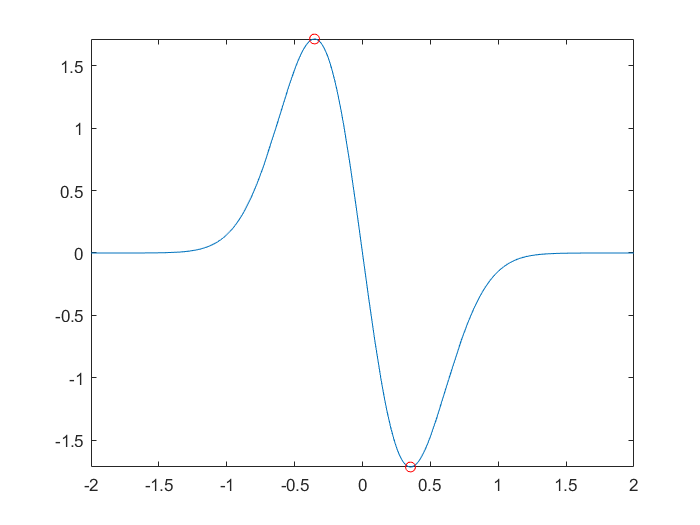


plot(stat_x, stat_y, 'or')